# ECSE 343: Numerical Methods in Engineering Final Project

In this project, three different methods will be implemented to find the transient responses of for all the voltage nodes, namely, V1, V2, and V3 for circuit shown in Figure 1.

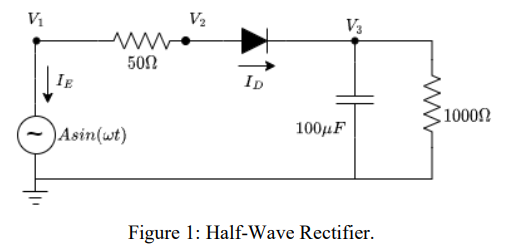

Using equations 1 and 2, the compact Modified Nodal Analysis form as seen in equation 3 is implemented.

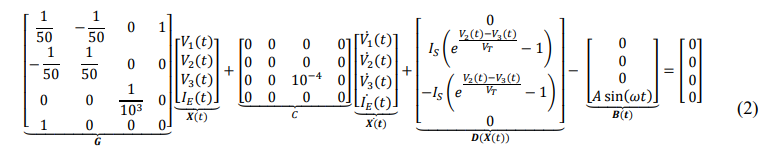

# Backward Euler Approximation

Using the backward euler approximation for the derivatives term ${X^{\prime } }_{n+1} \approx \frac{{X_{n+1} -X}_{n\;} }{\Delta t}$ and substituting in equation 3 gives us the difference equation,


$$G*\left(X_{n+1} \right)+C*\left(\frac{{X_{n+1} -X}_{n\;} }{\Delta t}\right)+D\left(X_{n+1} \right)-B_{n+1} =0$$


Which will be called $F\left(X_{n+1} \right)=G*\left(X_{n+1} \right)+C*\left(\frac{{X_{n+1} -X}_{n\;} }{\Delta t}\right)+D\left(X_{n+1} \right)-B_{n+1} =0$

$X_{n+1\;}$will be solved for every time step dT, where the Newton-Raphson Method will be used using direct Jacobian calculation.

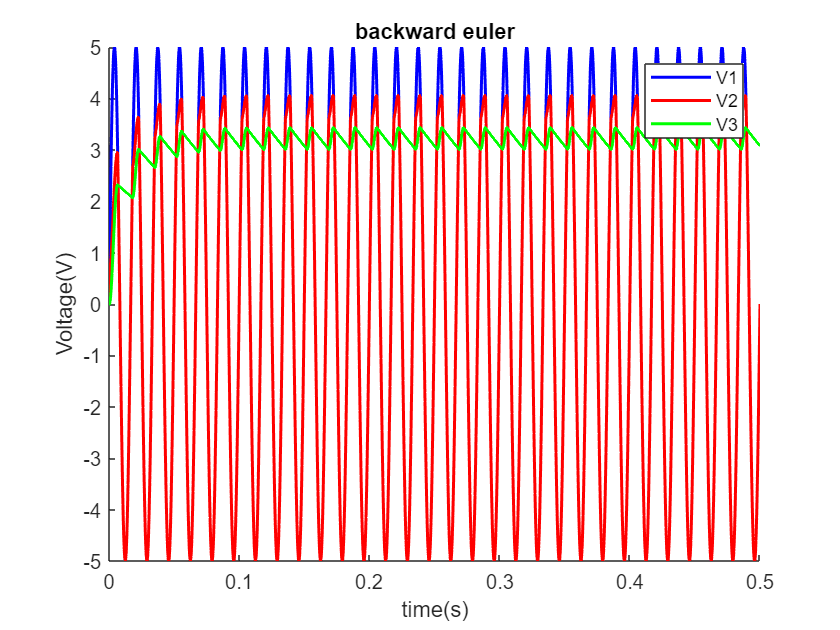

dT = 0.0001; % delta t
T = 0:dT:0.5;

%Initial conditions
V1 = 0;
V2 = 0;
V3 = 0;
Ie = 0;

% Xn
X = zeros(4,length(T));
X(:,1) = [V1; V2; V3; Ie];

for i=2:length(T)
    [Xout] = NR_Jacobian_bckwrd(X(:,i-1),X(:,i-1),1e-4,T(i),dT);
    X(:,i) = Xout;
end

figure()
title('backward euler')
xlabel('time(s)')
ylabel('Voltage(V)')
hold on
% plot solution here.
plot(T,X(1,:),'b-','LineWidth',1.5,'displayname','V1')
legend();
hold on
plot(T,X(2,:),'r-','LineWidth',1.5,'displayname','V2')
hold on
plot(T,X(3,:),'g-','LineWidth',1.5,'displayname','V3')

# Forward Euler Approximation

Using the forward euler approximation for the derivatives term ${X^{\prime } }_n \approx \frac{{X_{n+1} -X}_{n\;} }{\Delta t}$ and substituting in equation 3 gives us the difference equation,


$$F{\left(X_n ,X_{n+1} \right)}=GX_n +\frac{C}{\textrm{∆}t}{\left(X_{n+1} -X_n \right)}+D{\left(X_n \right)}-B_{n\ } =0\ \$$


$X_{n+1\;}$will be solved for every time step dT, where the Newton-Raphson Method will be used using direct Jacobian calculation.

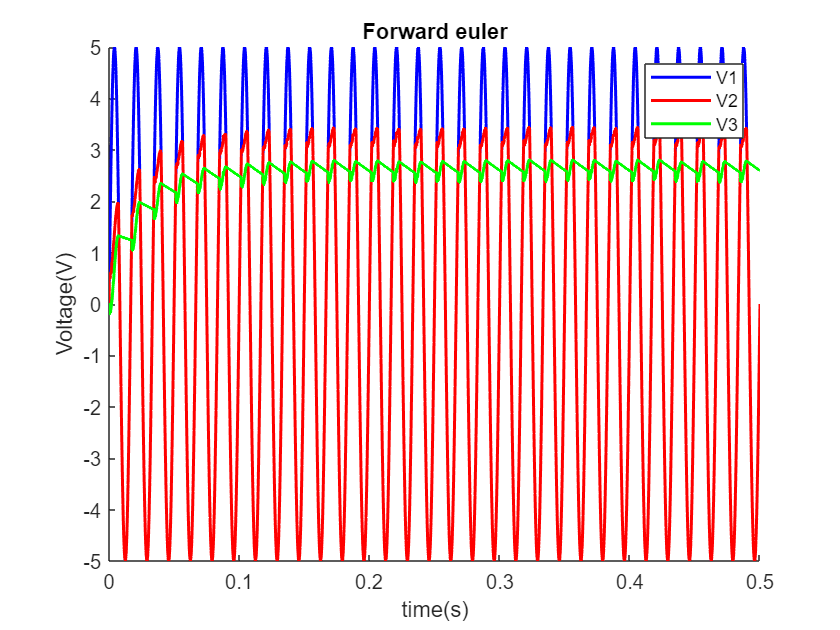

clear all;
dT = 0.0001; % delta t
T = 0:dT:0.5;

%Initial conditions
V1 = 0;
V2 = 0;
V3 = 0;
Ie = 0;

% Xn
X = zeros(4,length(T));
X(:,1) = [V1; V2; V3; Ie];
%Xguess = X;



for i=2:length(T)
    [Xout] = NR_Jacobian_frwrd(X(:,i-1),X(:,i-1),1e-4,T(i),dT);
    X(:,i) = Xout;
end


figure()
title('Forward euler')
xlabel('time(s)')
ylabel('Voltage(V)')
legend();
hold on
% plot solution here.
plot(T,X(1,:),'b-','LineWidth',1.5,'displayname','V1')
hold on
plot(T,X(2,:),'r-','LineWidth',1.5,'displayname','V2')
hold on
plot(T,X(3,:),'g-','LineWidth',1.5,'displayname','V3')

# Trapezoidal Rule

We can use the trapezoidal approximation, $X_{n+1} =X_n +\frac{\Delta t}{2}\left({X^{\prime } }_n +{X^{\prime } }_{n+1} \right)\Longrightarrow {X^{\prime } }_n +{X^{\prime } }_{n+1} =2\left(\frac{{\left(X\right.}_{n+1} -X_n }{\Delta t}\right)$, and substitute into the difference equation, which we define by adding $F\left(X_{n+1} \right)$ and $F\left(X_n \right)$ to give $F\left(X_{n+1} ,X_n \right)=G*\left(X_{n+1} +X_n \right)+C*\left({X^{\prime } }_n +{X^{\prime } }_{n+1} \right)+D\left(X_{n+1} \right)+D\left(X_n \right)-B_n -B_{n+1}$ 

After substituting we define the new function as,


$$F\left(X_{n+1} \right)=G*\left(X_{n+1} +X_n \right)+C*\left(2\left(\frac{{\left(X\right.}_{n+1} -X_n }{\Delta t}\right)\right)+D\left(X_{n+1} \right)+D\left(X_n \right)-B_n -B_{n+1}$$


$X_{n+1\;}$will be solved for every time step dT, where the Newton-Raphson Method will be used using direct Jacobian calculation.

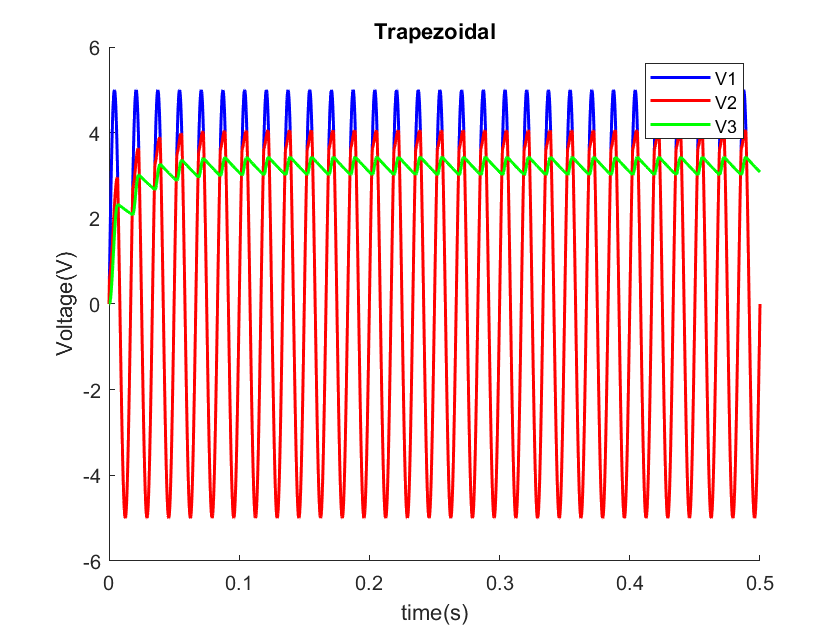

dT = 0.0001; % delta t
T = 0:dT:0.5;

%Initial conditions
V1 = 0;
V2 = 0;
V3 = 0;
Ie = 0;

% Xn
X = zeros(4,length(T));
X(:,1) = [V1; V2; V3; Ie];
%Xguess = X;

for i=2:length(T)
    [Xout] = NR_Jacobian_trapezoidal(X(:,i-1),X(:,i-1),1e-4,T(i),dT);
    X(:,i) = Xout;
end


figure()
title('Trapezoidal')
xlabel('time(s)')
ylabel('Voltage(V)')
legend();
hold on

% plot solution here.
plot(T,X(1,:),'b-','LineWidth',1.5,'displayname','V1')
hold on
plot(T,X(2,:),'r-','LineWidth',1.5,'displayname','V2')
hold on
plot(T,X(3,:),'g-','LineWidth',1.5,'displayname','V3')

# Appendix

function [Xout] = NR_Jacobian_bckwrd(x0, Xguess,tol,t,dt)

Is = 1e-13;
A = 5;
Vt = 0.025;
w = 2*pi*60; % f = 60Hz



% G Matrix
G = [1/50, -1/50, 0, 1; 
    -1/50, 1/50, 0, 0;
    0, 0, 1/(10^3), 0;
    1, 0, 0, 0];

% C Matrix
C = [0, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, 10^-4, 0;
    0, 0, 0, 0];

Bn = [0; 0; 0; A*sin(w*(t))];
%
Xout = Xguess;
counter = 1;
while 1
    % Calculate diode current
    Id = Is*(exp((Xout(2)-Xout(3))/Vt)-1);
    % Calculate D(x)
    Dx = [0; Id; -Id; 0];
    % Calculate Jacobian
    J = G+(C/dt)+[0, 0, 0, 0; 0, Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, -Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, 0; 0, -Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, 0; 0, 0, 0, 0];
    % Delta X = -(F(x)/J) where F(x) = G*(Xout)+(1/dt)*C*(Xout-x0)+Dx-Bn
    delX = -J\(G*(Xout)+(1/dt)*C*(Xout-x0)+Dx-Bn); 
    % Update Xout
    Xout = Xout + delX;

    if norm(delX)<tol
        break
    end
    if counter>1000
        break
    end
    counter = counter + 1;
end

end

function [Xout] = NR_Jacobian_frwrd(x0, Xguess,tol,t,dt)

Is = 1e-13;
A = 5;
Vt = 0.025;
w = 2*pi*60; % f = 60Hz



% G Matrix
G = [1/50, -1/50, 0, 1; 
    -1/50, 1/50, 0, 0;
    0, 0, 1/(10^3), 0;
    1, 0, 0, 0];

% C Matrix
C = [0, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, 10^-4, 0;
    0, 0, 0, 0];

Bn = [0; 0; 0; A*sin(w*(t))];
%
Xout = Xguess;
counter = 1;
while 1
    % Calculate diode current
    %Id = Is*(exp((x0(2)-x0(3))/Vt)-1);
    Id = Is*(exp((Xout(2)-Xout(3))/Vt)-1);
    % Calculate D(x)
    Dx = [0; Id; -Id; 0];
    % Calculate Jacobian
    J = G+(C/dt)+[0, 0, 0, 0; 0, Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, -Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, 0; 0, -Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, Is*(exp((Xout(2)-Xout(3))/Vt))/Vt, 0; 0, 0, 0, 0];
    % Delta X = -(F(x)/J)
    delX = -J\(G*x0+(1/dt)*C*(Xout-x0)+Dx-Bn);
    % Upadate Xout
    %x0 = x0 + delX;
    Xout = x0 + delX;
    %Xout = Xout+ delX;



    if norm(delX)<tol
        break
    end
    if counter>1000
        break
    end
    counter = counter + 1;
end

end

function [Xout] = NR_Jacobian_trapezoidal(x0, Xguess,tol,t,dt)

Is = 1e-13;
A = 5;
Vt = 0.025;
w = 2*pi*60; % f = 60Hz



% G Matrix
G = [1/50, -1/50, 0, 1; 
    -1/50, 1/50, 0, 0;
    0, 0, 1/(10^3), 0;
    1, 0, 0, 0];

% C Matrix
C = [0, 0, 0, 0;
    0, 0, 0, 0;
    0, 0, 10^-4, 0;
    0, 0, 0, 0];

% Calculate Bn
B = [0; 0; 0; A*sin(w*(t-dt))];
% Calculate Bn+1
Bn = [0; 0; 0; A*sin(w*(t))];

Xout = Xguess;
counter = 1;

Id_1 = Is*(exp((x0(2)-x0(3))/Vt)-1);
% calculate D(Xn)
Dx = [0; Id_1; -1*Id_1; 0];

while 1
    Id_2 = Is*(exp((Xout(2)-Xout(3))/Vt)-1);
    % Calculate D(Xn+1)
    Dxn = [0; Id_2; -1*Id_2; 0];
    J = G+((2*C)/dt)+[0, 0, 0, 0; 0, Is*(exp((Xout(2)-Xout(3))/Vt))*(1/Vt), -Is*(exp((Xout(2)-Xout(3))/Vt))*(1/Vt), 0; 0, -Is*(exp((Xout(2)-Xout(3))/Vt))*(1/Vt), Is*(exp((Xout(2)-Xout(3))/Vt))*(1/Vt), 0; 0, 0, 0, 0];
    % Delta X = -(F(x)/J) where F(x) = G*(Xout+x0)+(2/dt)*C*(Xout-x0)+Dx+Dxn-B-Bn
    delX = -J\(G*(Xout+x0)+(2/dt)*C*(Xout-x0)+Dx+Dxn-B-Bn); %-invJ*F(x+1,x)
    Xout = Xout + delX;

    if norm((G*(Xout+x0)+(2/dt)*C*(Xout-x0)+Dx+Dxn-B-Bn))<tol && norm(delX)<tol
        break
    end

    if norm(delX)<tol
        break
    end
    if counter>1000
        break
    end
    counter = counter + 1;
end

end